JFJ_st.name='JFJ'; 
JFJ_st.lat=46.55;
JFJ_st.lon=7.99;
JFJ_st.alt=3580;
JFJ_st.env='Mt';
JFJ_st.footp='Mx';


JFJ_rd=read_betsy('jfj_2000_2014',JFJ_st.name);

load('env_2018.mat', 'ae31');
load('env_2018.mat', 'ae880_annales');
load('env_2018.mat', 'tsi');
load('env_2018.mat', 'tsi_ae31');
load('env_2018.mat', 'maap'); 
load('env_2018.mat', 'cpc'); 


JFJ_rd0=timetable(datetime(datevec(tsi.start_time)));
JFJ_rd0.BsB=tsi.sc450t;
JFJ_rd0.BsG=tsi.sc550t;
JFJ_rd0.BsR=tsi.sc700t;
JFJ_rd0.BbsB=tsi.bsc450t;
JFJ_rd0.BbsG=tsi.bsc550t;
JFJ_rd0.BbsR=tsi.bsc700t;


JFJ_rd1=timetable(datetime(datevec(ae31.start_time)));
JFJ_rd1.Ba1=ae31.abs370;
JFJ_rd1.Ba2=ae31.abs470;
JFJ_rd1.Ba3=ae31.abs520;
JFJ_rd1.Ba4=ae31.abs590;
JFJ_rd1.Ba5=ae31.abs660;
JFJ_rd1.Ba6=ae31.abs880;
JFJ_rd1.Ba7=ae31.abs950;

JFJ_rd2=timetable(datetime(datevec(cpc.start_time)));
JFJ_rd2.N=cpc.conc;

JFJ_rd3=timetable(datetime(datevec(maap.start_time)));
JFJ_rd3.BaR=maap.abs637;

JFJ_rd=synchronize(JFJ_rd0,JFJ_rd1,JFJ_rd2,JFJ_rd3);


pxx=timerange('2014-01-01','2015-01-01');
JFJ_rdt=JFJ_rd;
    JFJ_rdt.BsB(pxx)=GAW2014EMEP2.BlueSc;
    JFJ_rdt.BsG(pxx)=GAW2014EMEP2.GreenSc;
    JFJ_rdt.BsR(pxx)=GAW2014EMEP2.RedScat;
    JFJ_rdt.BbsB(pxx)=GAW2014EMEP2.BlueBSc;
    JFJ_rdt.BbsG(pxx)=GAW2014EMEP2.GreenBSc;
    JFJ_rdt.BbsR(pxx)=GAW2014EMEP2.RedBSc;

JFJ_14.BbsB=CH0001G.VarName3;
JFJ_14.BbsG=CH0001G.VarName6;
JFJ_14.BbsR=CH0001G.VarName9;
JFJ_14.BsB=CH0001G.VarName12;
JFJ_14.BsG=CH0001G.VarName15;
JFJ_14.BsR=CH0001G.VarName18;
nn=fieldnames(CH0001G);
for i=3:20
ind=CH0001G.(nn{i})>99;
CH0001G.(nn{i})(ind)=NaN;
end
pxx=timerange('2014-01-01','2015-01-01');

    JFJ_rd.BsB(pxx)=CH0001G.VarName13.*1e-6;
    JFJ_rd.BsG(pxx)=CH0001G.VarName16.*1e-6;
    JFJ_rd.BsR(pxx)=CH0001G.VarName19.*1e-6;
    JFJ_rd.BbsB(pxx)=CH0001G.VarName4.*1e-6;
    JFJ_rd.BbsG(pxx)=CH0001G.VarName7.*1e-6;
    JFJ_rd.BbsR(pxx)=CH0001G.VarName10.*1e-6;

JFJ_rd=retime(JFJ_rd,'daily',@nanmedian);

datevec(JFJ_rd.Time(1))

ans =         1995           1           1           0          30           0

datevec(JFJ_rd.Time(end))

ans =         2019           1           1           0           0           0

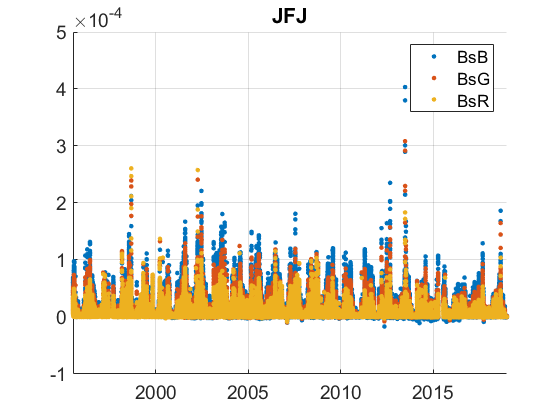

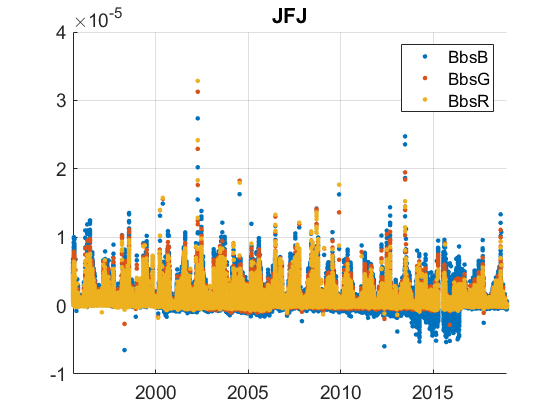

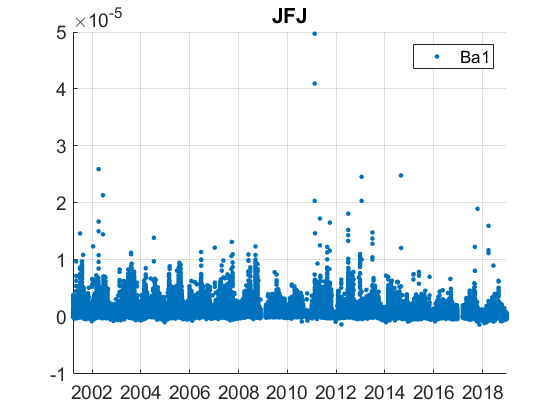

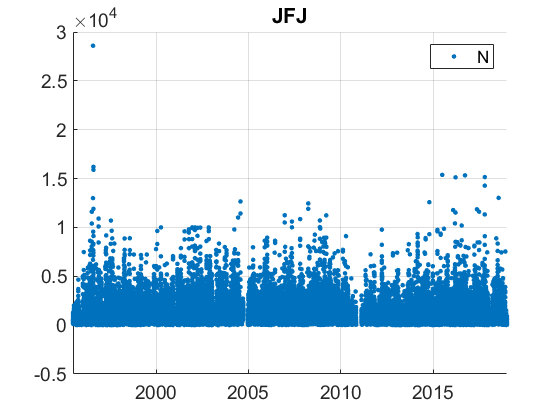

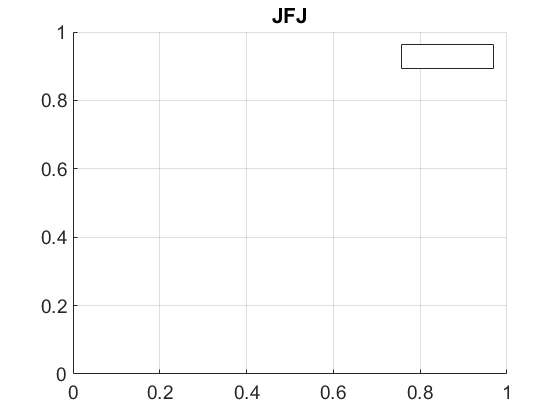

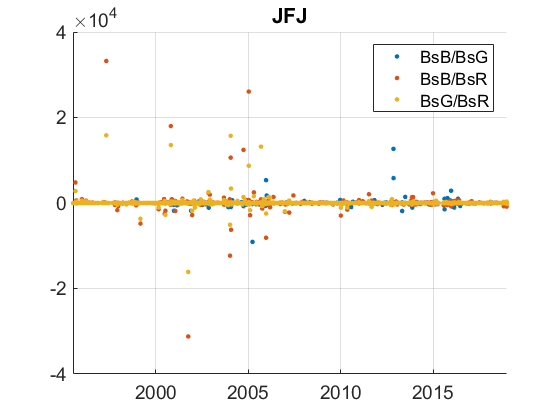

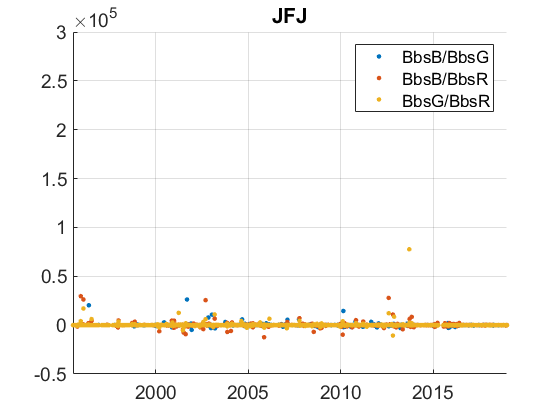

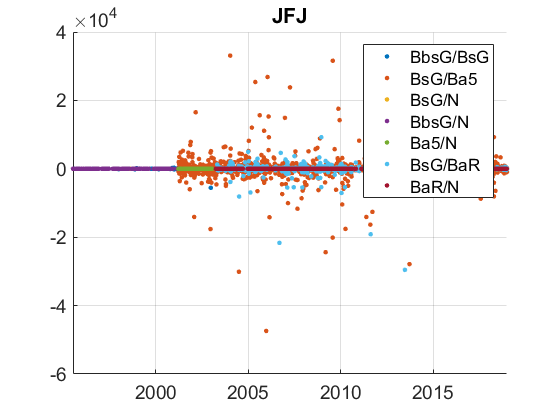

%prctile(JFJ_rd.U_S11,[5 50 95])
%  prctile(JFJ_rd.U0_S,[5 50 95])
%  prctile(JFJ_rd.U1_S,[5 50 95])
%prctile(tsi.indU,[5 50 95])
plotFigControl(JFJ_rd,JFJ_st.name);

% ? size cut, ok
% sc: ok, ? negatives,? clear seasonal cycle

namesOK=fieldnames(JFJ_rd);
Cb=startsWith(namesOK,'B');
namesC=namesOK(Cb);
for i=1:length(namesC)
    
JFJ_rd.(namesC{i})=JFJ_rd.(namesC{i}).*1e6;
end

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
JFJ_cal=compute_exp_SSA(JFJ_rd,lambdaSC, lambdaAE);

SCexclus = 95716

ans = 12018

ans = 79025

ans = 301

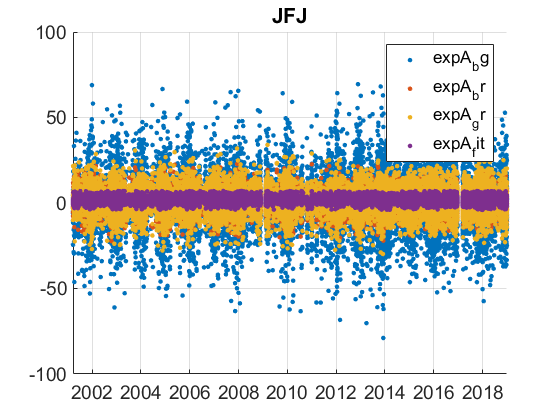

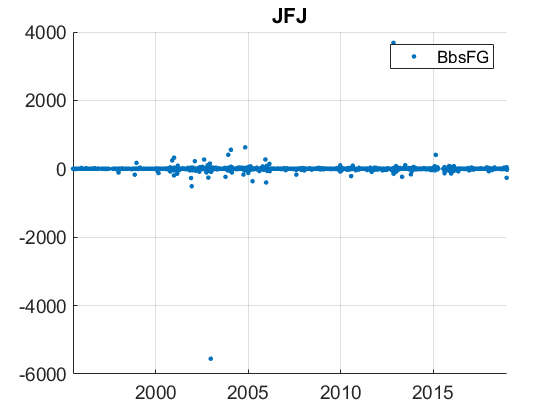

JFJ_cal.SSAG=JFJ_rd.BsG./(JFJ_rd.BsG+JFJ_rd.Ba3);
JFJ_cal.BbsFR=JFJ_rd.BbsR./JFJ_rd.BsR;
JFJ_cal.BbsFB=JFJ_rd.BbsB./JFJ_rd.BsB;

JFJ_cal.expS_bg=real(-log(JFJ_rd.BsB./JFJ_rd.BsG)/log(lambdaSC(1)/lambdaSC(2)));
JFJ_cal.expS_gr=real(-log(JFJ_rd.BsG./JFJ_rd.BsR)/log(lambdaSC(2)/lambdaSC(3)));
%compute expS and SSA
plotFigControl_cal(JFJ_cal, JFJ_st.name);

%Questions:
%problems:

%nephelometer:
% % 	Use green scat and backscat
% % 	Use gr exponent
% % 	BbsF should be only used between 2001 and 2016 due to the deleted negatives and the rupture in 2016 when the calibration and reparation of the TSI nephelometer occurred.


JFJ_tr=JFJ_rd;
JFJ_tr.y=year(JFJ_tr.Time);
% begin at the beginning of a year:1996 for the nephelometer, 2002 for AE31
% and BbsF

P=timerange('1996-01-01','2019-01-01');
JFJ_tr=JFJ_tr(P,:);

%no MAAP used
JFJ_tr.BaR=[];
%abs since 2002

pA=timerange('1996-01-01','2002-01-01');
names=fieldnames(JFJ_tr);
c= startsWith(names,["Ba"]) ;
N=names(c);
for i=1:length(N)
    JFJ_tr.(N{i})(pA)=NaN;
end

JFJ_cal2=compute_exp_SSA(JFJ_tr,lambdaSC, lambdaAE);
JFJ_cal2.SSAG=JFJ_tr.BsG./(JFJ_tr.BsG+JFJ_tr.Ba3);
JFJ_cal2.BbsFR=JFJ_tr.BbsR./JFJ_tr.BsR;
JFJ_cal2.BbsFB=JFJ_tr.BbsB./JFJ_tr.BsB;

JFJ_cal2.expS_bg=real(-log(JFJ_tr.BsB./JFJ_tr.BsG)/log(lambdaSC(1)/lambdaSC(2)));
JFJ_cal2.expS_gr=real(-log(JFJ_tr.BsG./JFJ_tr.BsR)/log(lambdaSC(2)/lambdaSC(3)));

JFJ_tr=outerjoin(JFJ_tr, JFJ_cal2);
% use Bbsf only between 2001 and 2015
p1=timerange('1996-01-01','2001-01-01');
p2=timerange('2016-01-01','2019-01-01');
JFJ_tr.BbsFG(p1)=NaN;
JFJ_tr.BbsFG(p2)=NaN;

%use only green + test trend on red due to problem before reparation
JFJ_tr.BsB=[];
JFJ_tr.BbsB=[];
JFJ_tr.BbsFB=[];
JFJ_tr.BbsFR=[];

%use only expS gr
JFJ_tr.expS_bg=[];
%use only AE31 gree
JFJ_tr.Ba1=[];
JFJ_tr.Ba2=[];
JFJ_tr.Ba4=[];
JFJ_tr.Ba5=[];
JFJ_tr.Ba6=[];
JFJ_tr.Ba7=[];

%N bug sur 10 ans
JFJ_tr.N=[];

 JFJ_result= all_trend_STN(JFJ_tr,JFJ_st);
 plot_10y_in_two(JFJ_result,JFJ_st);

%used trends for paper:
% do not used neph red, use only expA_fit
JFJ_result_D=JFJ_result;
JFJ_result_D=JFJ_result_D(strcmp(JFJ_result_D.parameter,'BsG')==1 |strcmp(JFJ_result_D.parameter,'BbsG')==1 |strcmp(JFJ_result_D.parameter,'BbsFG')==1 |strcmp(JFJ_result_D.parameter,'Ba3')==1 |...
    strcmp(JFJ_result_D.parameter,'expS_gr')==1 |strcmp(JFJ_result_D.parameter,'expA_fit')==1 |strcmp(JFJ_result_D.parameter,'SSAG')==1,:);


Error using strcmp
Inputs must be the same size or either one can be a scalar.